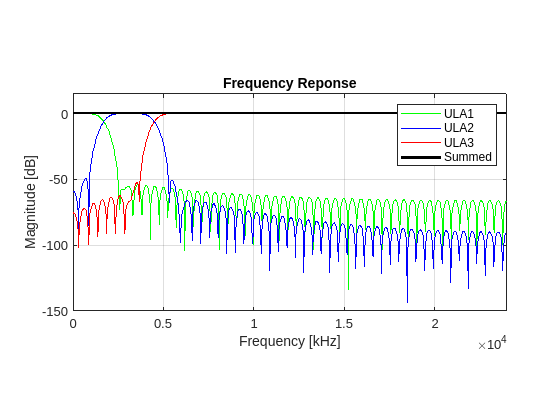

clc
clear
close all

fs = 48e3;
c = 1496;

cfULA1 = 1700;
cfULA2 = [cfULA1 4500];
cfULA3 = cfULA2(2);

% FIRULA1 = makeFIR(cfULA1, 100, fs, 'low');
% FIRULA2 = makeFIR(cfULA2, 100, fs, 'bandpass');
% FIRULA3 = makeFIR(cfULA3, 100, fs, 'high');

FIRULA1 = fir1(100, 2*cfULA1/fs, 'low');
FIRULA2 = fir1(100, 2*cfULA2/fs, 'bandpass');
FIRULA3 = fir1(100, 2*cfULA3/fs, 'high');

%freqz(FIRULA1,1,1024,fs);

[HULA1,w] = freqz(FIRULA1,1,1024,fs);
[HULA2,w] = freqz(FIRULA2,1,1024,fs);
[HULA3,w] = freqz(FIRULA3,1,1024,fs);

plot(w,20*log10(abs(HULA1)), 'Color', 'g');
hold on
plot(w,20*log10(abs(HULA2)), 'Color', 'b');
plot(w,20*log10(abs(HULA3)), 'Color', 'r');
plot(w,20*log10(abs(HULA1+HULA2+HULA3)), 'Color', 'black', 'LineWidth',2);

legend('ULA1', 'ULA2', 'ULA3', 'Summed')

title('Frequency Reponse')
xlabel('Frequency [kHz]')
ylabel('Magnitude [dB]')
pbaspect([2 1 1])
grid
xlim([0 fs/2])
ylim([-150 15])
hold off

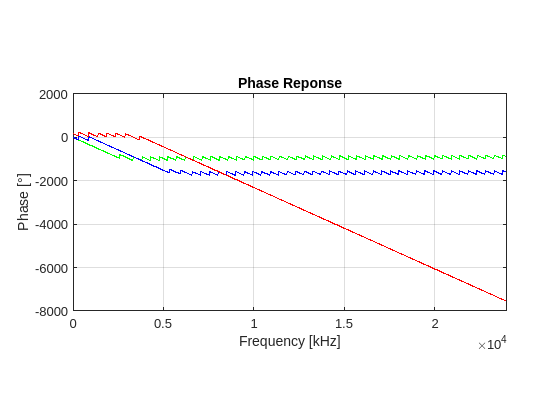


plot(w,180/pi*unwrap(angle(HULA1)), 'Color', 'g');
hold on
plot(w,180/pi*unwrap(angle(HULA2)), 'Color', 'b');
plot(w,180/pi*unwrap(angle(HULA3)), 'Color', 'r');
title('Phase Reponse')
xlabel('Frequency [kHz]')
ylabel('Phase [°]')
pbaspect([2 1 1])
grid
xlim([0 fs/2])
hold off


% plot(w,20*log10(abs(HULA1+HULA2+HULA3)), 'Color', 'black');
% hold on
% 
% 
% title('Frequency Reponse')
% xlabel('Frequency [kHz]')
% ylabel('Magnitude [dB]')
% pbaspect([2 1 1])
% grid
% xlim([0 fs/2])
% ylim([-150 15])
% hold off

% freqz(FIRULA1,1,1024,fs);



function coeffs_adjusted = makeFIR(Fc, order, fs, type)
if ~exist('type', 'var') 
    coeffs = fir1(order,2*Fc/fs);
else 
    coeffs = fir1(order,2*Fc/fs, type);
end 
[mag, freq] = freqz(coeffs,1,1024,fs);
magdB = 20*log10(abs(mag));
if length(Fc) == 1
    [~, minIndex] = min(abs(magdB + 3));
    Fc_3dB = freq(minIndex);
    Fc_adjusted = Fc * (Fc/Fc_3dB);
    coeffs_adjusted = fir1(order, 2*Fc_adjusted/fs, type);
elseif length(Fc) == 2
    %[~, minIndexLow] = min(abs(magdB + 3));
    minIndexLow = find(abs(magdB)<3,1);
    minIndexHigh = find(abs(magdB(minIndexLow:end))>3,1) + minIndexLow;
    FcLow_3dB = freq(minIndexLow);
    FcHigh_3dB = freq(minIndexHigh);
    FcLow_adjusted = Fc(1) * (Fc(1)/FcLow_3dB);
    FcHigh_adjusted = Fc(2) * (Fc(2)/FcHigh_3dB);
    coeffs_adjusted = fir1(order, 2*[FcLow_adjusted FcHigh_adjusted]/fs, type);
else
    disp("nederen")
end
end